# Spatial Temporial Koopman decompsition for crypto-valuation prediction

#### `Anirudh Bhaskar`

#### `Anirudh Vadakedath`

#### `Rohith Ramakrishnan`

## Abstract

A prediction analysis applied on a dynamical system such as crypto currency using the principles of spatio temporial koopman decomposition for a higher dimensions. We go through the basic theory with our data-driven approach using higher order dynamic mode decomposition taking certain dimensions from sentiment analysis from news and tweets generated on the topic "Bitcoin" and "Dogecoin" which are famous crypto-currency in circulation in the economy.

## Introduction on Mathematical Concepts used:

## Singular Value Decomposition

Consider $\vec{x}= \pmatrix{1 \cr 3} $ and $A = \pmatrix{2 & 1 \cr -1 & 1}$, then $\vec{y} = A\bar{x}=\pmatrix{2 & 1 \cr -1 & 1}\pmatrix{1 \cr 3} = \pmatrix{5\cr 2}$. $\overrightarrow{y}$ is basically a rotated and stretched form of $\overrightarrow{x}$. 

Now $\pmatrix{\cos{\theta} & -\sin{\theta} \cr \sin{\theta} & \cos{\theta} }$ is a rotation matrix and $\pmatrix{\alpha & 0 \cr 0 & \alpha}$, where $\alpha$ is a *positive real number*, is a stretching/translational matrix and $A$ is composed of these two.

Now consider a circle in 2-dimensions with its orthogonal direction co-ordinates being $v_1$ and $v_2$.

*(in n-dimensions it would be *$v_1 ,v_2 ,\;\ldotp \ldotp \ldotp \;,v_n$*)*

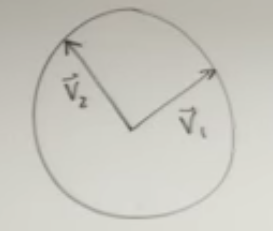

When an $A_{\textrm{mxn}}$, is operated on this circle it becomes an ellipse (*it is rotated and then stretched*):

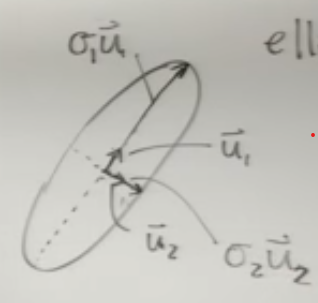

where $u_1$ and $u_2$ are the unit vectors in those directions and $\sigma_1$ and $\sigma_2$ are the distances along the unit vectos.

$\therefore $ $v_1 ,v_2 ,\;\ldotp \ldotp \ldotp \;,v_n$ vector space gets transformed to $u_1 ,u_2 ,\;\ldotp \ldotp \ldotp \;,u_n$ with $\sigma_1 ,\sigma_2 ,\;\ldotp \ldotp \ldotp \;,\sigma_n$ as stretching factors, when multiplied by $A$. The $\sigma_1 ,\sigma_2 ,\;\ldotp \ldotp \ldotp \;,\sigma_n$ are known as the ***singular values***.

Therefore in vector terms: $A\vec{v_j}=\sigma_j \vec{u_j}, \ j=1, 2, ..., n$.


$$\left[ \matrix{\cr A \cr \ } \right]_{mxn}
\left[\matrix{ \vec{v_1} & \vec{v_2} & ... & \vec{v_n} } \right]_{nxn} = 
\left[\matrix{ \vec{u_1} & \vec{u_2} & ... & \vec{u_n} } \right]_{mxn}
\left[\matrix{\sigma_1 &  &  & 0 \cr & \sigma_2 & & \cr  & & \ddots & \cr 0 & & & \sigma_n} \right]_{nxn}$$



$$\therefore
$$

$$\textrm{AV}=\hat{U} \Sigma^ˆ$$


from $V$ and $\hat{U}$ it could be seen that these are unitary transformation matrices and orthogonal too. Thus $V^{-1} =V^*$and ${\hat{U} }^{-1} ={\hat{U} }^*$. On right multiplication with $V^{-1}$ we get

$A=\hat{U} \Sigma^ˆ V^*$ $\longrightarrow$ reduced SVD of A.

Since $\hat{U}$ is of size mxn, m-n extra silent columns can be added to make it mxm and the $\Sigma^ˆ$ can be stretched with m-n rows of 0's to make its size mxn.

$\therefore \  A_{mxn} = U_{mxm}\Sigma_{mxn} V^{*}_{nxn}$ $\longrightarrow$ **Singular Value Decomposition** of $\mathit{\mathbf{A}}$, where 

($\sigma_1 \ge \sigma_2 \ge \;\ldotp \ldotp \ldotp \;\ge \sigma_n \ge 0$).

To get the $U,\Sigma \;\textrm{and}\;V$ matrices we follow these steps:


$$A^T A = (U \Sigma V^*)^T (U \Sigma V^*) \\
A^T A = V \Sigma  U^* U \Sigma V^* \\
A^T A = V \Sigma^2 V^*\\
A^T A V = (V \Sigma^2 V^*)V\\
\therefore A^T A V = \Sigma^2 V$$


This is the same as $\textrm{Av}=\lambda v$, thus by solving this eigen-value problem we would get the $\Sigma^2$ and $V$ values.


$$A A^T = (U \Sigma V^*) (U \Sigma V^*)^T \\
A A^T = U \Sigma V^* V \Sigma U^* \\
A A^T = U \Sigma^2 U^* \\
A A^T U = (U \Sigma^2 U^*)U \\
\therefore A A^T U = \Sigma^2 U$$


clear all;close all;clc;
A = randi(10,3);
[u1, s1, v1] = svd(A);
[v2,ss21] = eig(A'*A);
[u2, ss12] = eig(A*A');
s2 = sqrt(ss12);
u1

u1 =    -0.6252    0.5269    0.5758
   -0.4124    0.4033   -0.8168
   -0.6626   -0.7481   -0.0349


u2

u2 =     0.5758    0.5269    0.6252
   -0.8168    0.4033    0.4124
   -0.0349   -0.7481    0.6626


disp("*****")

*****


s1

s1 =    12.2010         0         0
         0    7.1490         0
         0         0    5.1018


s2

s2 =     5.1018         0         0
         0    7.1490         0
         0         0   12.2010


disp("*****")

*****


v1

v1 =    -0.5502    0.4804   -0.6830
   -0.6066    0.3321    0.7223
   -0.5738   -0.8117   -0.1088


v2

v2 =     0.6830    0.4804    0.5502
   -0.7223    0.3321    0.6066
    0.1088   -0.8117    0.5738


$A^T A$ $\textrm{and}$ ${\textrm{AA}}^T$ are hermition matrices thus the eigen values are ***always*** *positive, real and distinct*.

## Dynamic Mode Decomposition

A method to reduce the dimensionality of an algorithm. It is seen as an application extracted from the idea of Koopman Spectral analysis.

We consider this method to be more data-driven and on futher explain DMD for higher order dimension non-linear systems. 

Basic idea

Non-linear to best linear approximation,


$$\frac{d\overset{\_}{x} }{\textrm{dt}}=f\left(\overset{\_}{x} ,t,\mu \right)\to \frac{d\overset{\_}{x} }{\textrm{dt}}=A\overset{\_}{x}$$


We measure $x$ for any time-point,


$$x_j =\overset{\_}{x} \left(t_j \right)$$


So,


$$\begin{array}{l}
X=\left\lbrack x_1 \;\;\;x_2 \;\;\;\;x_3 \;\;\cdots \cdots \;\;x_{m-1} \;\right\rbrack \\
X\;\prime =\left\lbrack x_2 \;\;\;x_3 \;\;\;\;x_4 \;\;\cdots \cdots \;\;x_m \;\right\rbrack 
\end{array}$$


Our objective is to find the best matrix that takes $X$ to $X\;\prime \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \;X\;\prime =\textrm{AX}$

Here matrix** A** is seen as an operator that takes us $\Delta t$ times into the future from $X\;\textrm{to}\;X\;\prime$

Now from the equation we can calculate $X$ by multiplying its respective pseudo inverse on both sides,

Final equation $\longrightarrow \;A=X\;\prime X^+$ 

This equation is the exact depiction of working of DMD but cannot be practically implemented in data-driven cases. Given our $X$ is has N columns multiplied by N rows of its pseudo inverse we get NxN matrix **A** which is computationally not feasible. So we can define it as an algorithm.

**Step 1:** Decompose $X$ using SVD 

                    
$$X=U\Sigma V^*$$


       We reduce the rank using rank truncation and use that as the subspace for building the model

                    
$$X=U_r \Sigma_r {V^* }_r$$
 

**Step 2:**   

                  
$$\begin{array}{l}
A=X\;\prime X^+ \\
\;\;\;\;=X\;\prime \;V\;\Sigma^{-1} {\;U}^* 
\end{array}$$
 

        We will be working with a similarity transform of A dentoted as $\overset{~}{A}$

                   
$$\begin{array}{l}
\overset{~}{A} =U^* A\;U\\
{\overset{~}{A} }_{\;\textrm{rxr}} ={\;U}^* X\;\prime \;V\;\Sigma^{-1} 
\end{array}$$


**Step 3:**

        we do an eigenvalue decomposition

                    
$$\hat{\;A} W=W\Lambda$$


       where $W\;\textrm{is}\;\left\lbrack \begin{array}{c}
\textrm{eigenvectors}
\end{array}\right\rbrack \;\textrm{and}\;\Lambda \;\textrm{is}\;\left\lbrack \begin{array}{ccc}
\lambda_1  & \cdots  & 0\\
\vdots  & \ddots  & \vdots \\
0 & \cdots  & \lambda_r 
\end{array}\right\rbrack \;$

**Step 4:**

       Bring it back to the original higher rank

                    
$$\phi =X\;\prime \;V\;\Sigma^{-1} \;W\;\;\longrightarrow \;\;\textrm{DMD}\;\textrm{modes}$$



$$X\left(t\right)=\phi {\;e}^{\Omega t} \;b\;\;=\;\sum_{k=1}^r \phi_k \;e^{w_k \;t} \;b_k \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{where}\;\;\;\;\;b=\frac{\phi }{x\left(0\right)}\;$$


x=linspace(-10,10,100); 
t=linspace(0,4*pi,80); dt=t(2)-t(1);
[X,T]=meshgrid(x,t); 

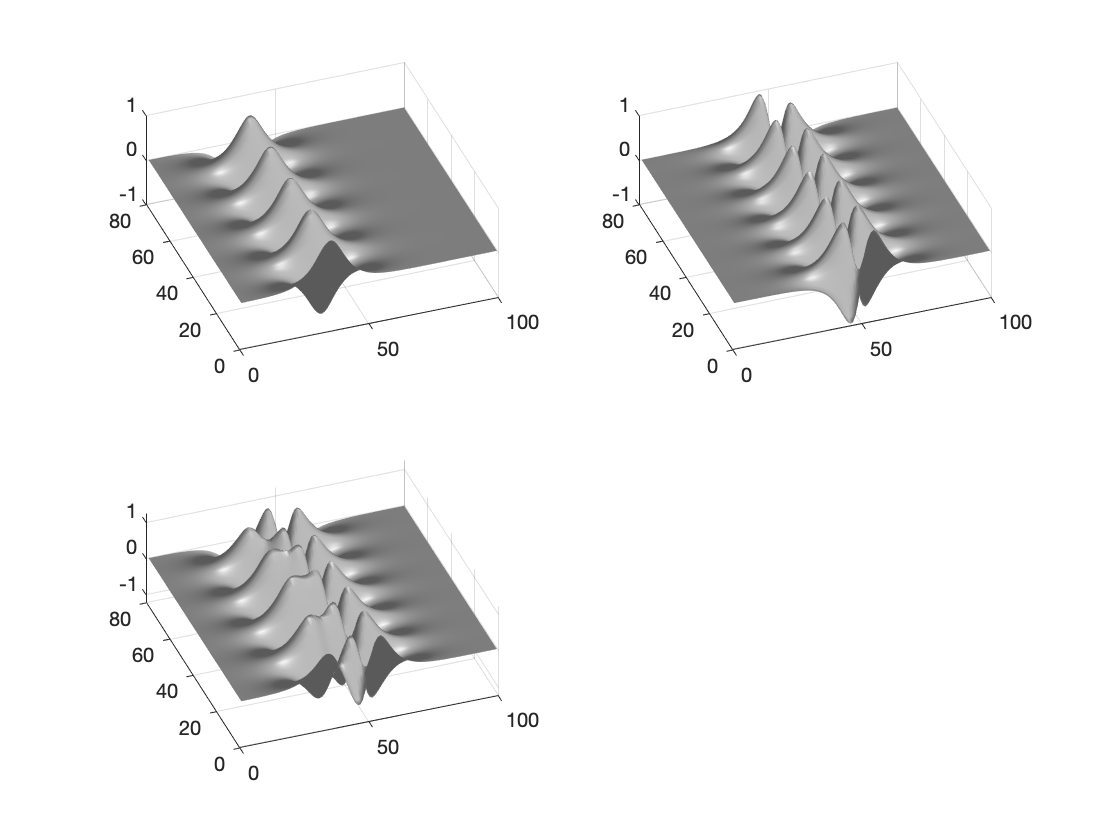

f1=sech(X+3).*(1*exp(i*2.3*T));
f2=(sech(X).*tanh(X)).*(2*exp(i*2.8*T));
f=f1+f2;
 
subplot(2,2,1), surfl(real(f1)), shading interp, colormap(gray), view(-20,60)
subplot(2,2,2), surfl(real(f2)), shading interp,colormap(gray), view(-20,60)
subplot(2,2,3), surfl(real(f)), shading interp,colormap(gray), view(-20,60) 

[u,s,v]=svd(f');
 
figure(2)
subplot(4,3,1), plot(diag(s)/sum(diag(s)),'ko','Linewidth',[2])
subplot(4,1,2), plot(t,v(:,1)/max(v(:,1)),t,v(:,2)/max(v(:,2)),'Linewidth',[2])

subplot(4,1,3), plot(x,u(:,1)/max(u(:,1)),'Linewidth',[2])

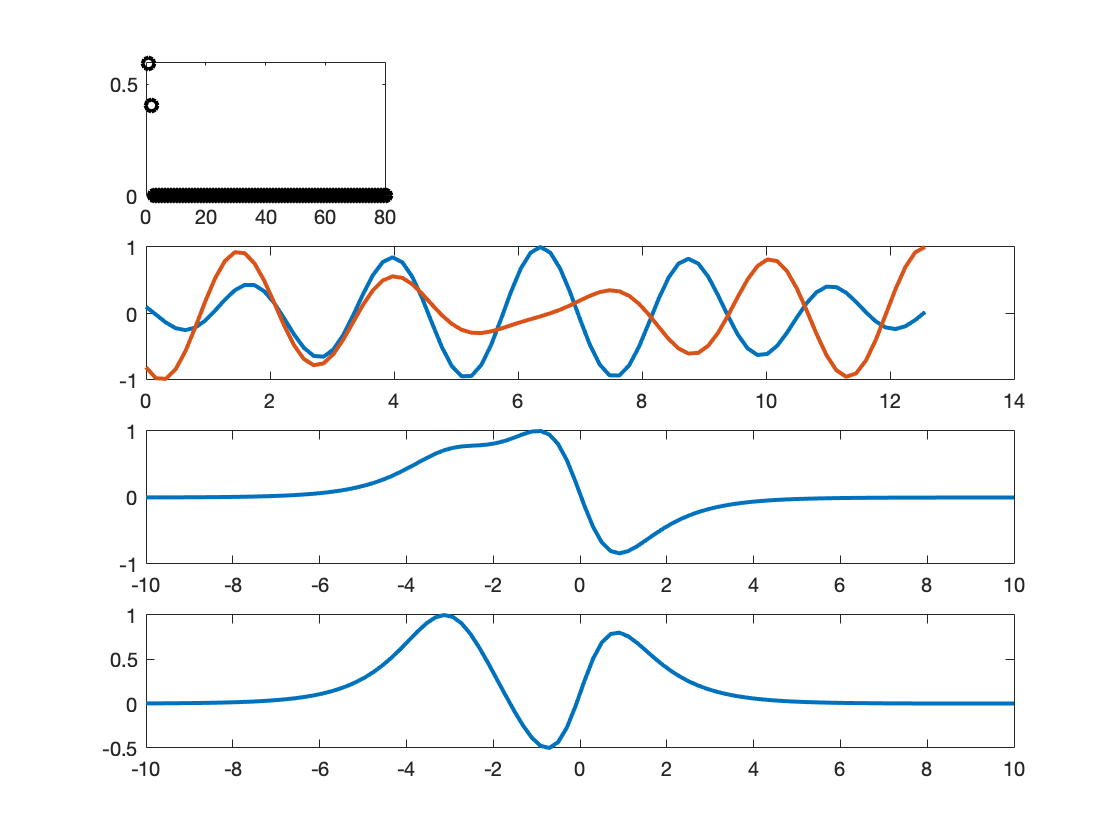

subplot(4,1,4), plot(x,u(:,2)/max(u(:,2)),'Linewidth',[2])

X = f.'; X1 = X(:,1:end-1); X2 = X(:,2:end);
r=2;

[U2,Sigma2,V2] = svd(X1,'econ'); U=U2(:,1:r); Sigma=Sigma2(1:r,1:r); V=V2(:,1:r);
Atilde = U'*X2*V/Sigma;    
[W,D] = eig(Atilde);    
Phi = X2*V/Sigma*W;
    
mu = diag(D);
omega = log(mu)/dt;

u0=f(1,:).';
y0 = Phi\u0;  % pseudo-inverse initial conditions
u_modes = zeros(r,length(t));
for iter = 1:length(t)
     u_modes(:,iter) =(y0.*exp(omega*t(iter)));
end
u_dmd = Phi*u_modes;

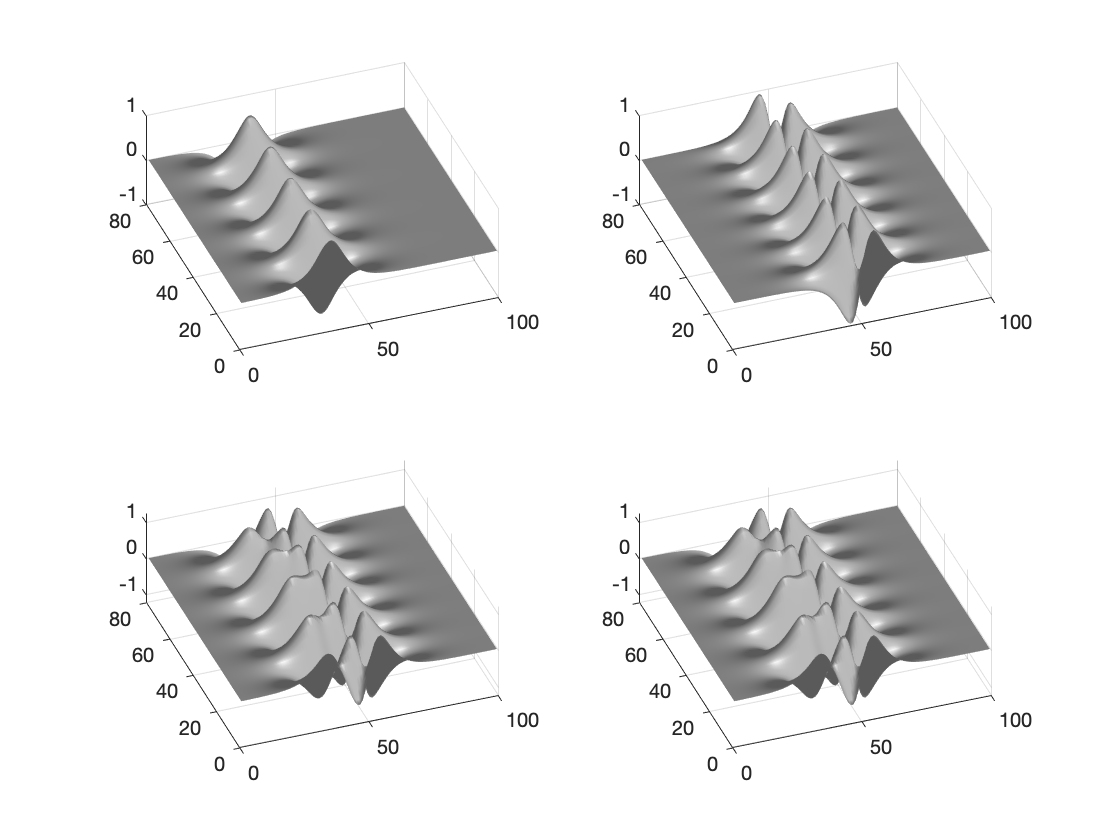

figure(1)
subplot(2,2,4)
surfl(real(u_dmd.')), shading interp,colormap(gray), view(-20,60)


figure(2), 
subplot(4,3,2), plot(diag(Sigma2)/sum(diag(Sigma2)),'ko','Linewidth',[2])
subplot(4,1,3), hold on, plot(x,-Phi(:,1)/max(Phi(:,1)),'Linewidth',[2])

subplot(4,1,4), hold on, plot(x,Phi(:,2)/max(Phi(:,2)),'Linewidth',[2])

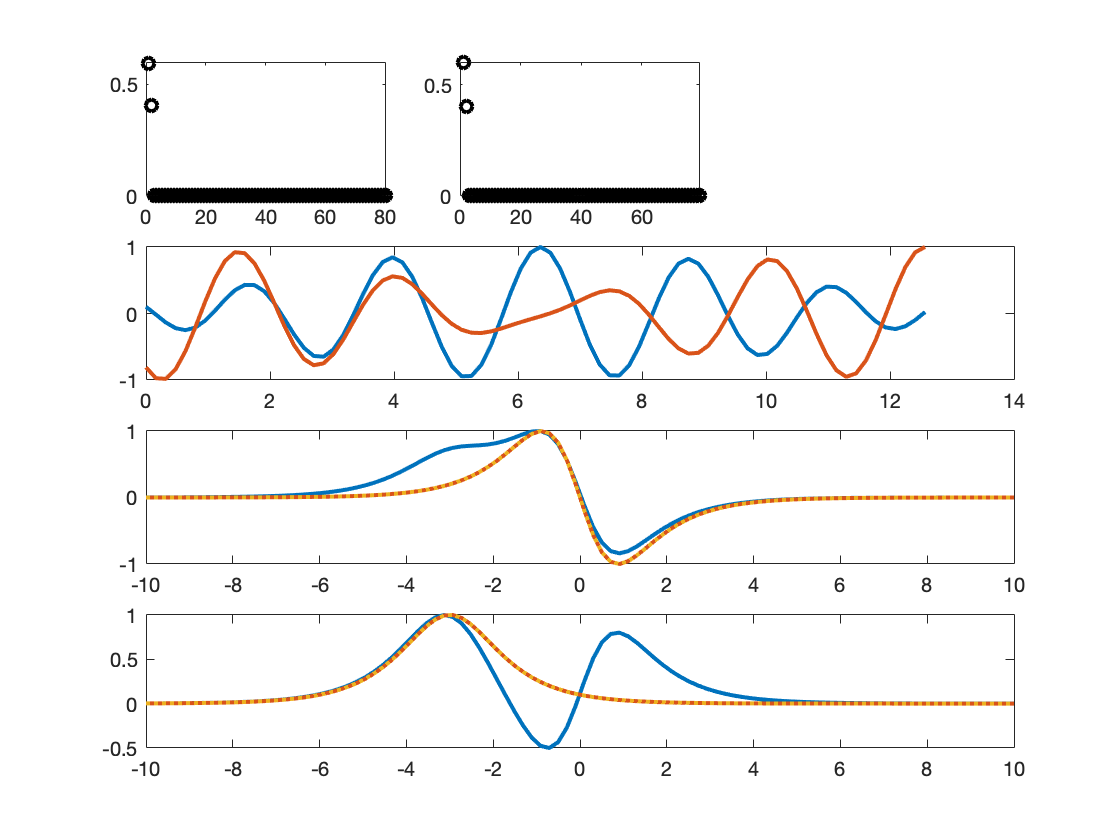


subplot(4,1,3), plot(x,-sech(x).*tanh(x)/max(sech(x).*tanh(x)),':','Linewidth',[2])
subplot(4,1,4), plot(x,sech(x+3)/max(sech(x+3)),':','Linewidth',[2])

##  Higher Order Dynamic Mode Decomposition

Lets assume a dynammic system given by the vector state variable **𝑣**(𝑡), of size 𝐽, we consider a set of 𝐾 snapshots at equispaced values of *t*

				
$$v_k \equiv v\left(t_k \right)\;$$


where $t_k =t_1 +\left(k-1\right)\ldotp \Delta t\;,\textrm{for}\;\textrm{𝑘}=1,\ldotp \ldotp \ldotp ,\textrm{𝐾}$

Assuming the dynamical system is infinite-dimensional, the finite- dimensional state vector V generally results from spatial discretization. The snapshots

are organized in a snapshot matrix (whose columns are the snapshots), as 

                            
$$V_1^k =\left\lbrack \upsilon_1 \;\;\;\;\upsilon_2 \;\;\;\ldotp \ldotp \ldotp \;\;\;\upsilon_k \right\rbrack$$


**Metrics: ** *relative root mean square *(RMS) error, defined as 

            
$$\textrm{error}=\sqrt{\frac{\sum_{k=1}^K {\left\|\;v_k^{\textrm{approx}} \;-v_k \right\|}_2^2 }{\sum_{k=1}^K {\left\|\;v_k \right\|}_2^2 }}$$


### Algorithm:

**SVD** : 

For dimensionality reduction, truncated SVD is applied to $V_1^k$, which yields,

                $V_1^k \approx P\Sigma Q^T$ $\equiv P\hat{{{\mathrm{T}}_1 }^K }$    (or $\upsilon_k$ $\equiv P\hat{t_k }$)

                            where $\hat{{\mathrm{T}}_1 }$ = $\Sigma Q^T$ 

where the matrix $\hat{{{\mathrm{T}}_1 }^K }$ is known as the dimension-reduced snapshot matrix and their columns, the *dimension-reduced snapshots*,$\hat{{\;t}_k }$.

**DMDd**: 	

For ordinary DMD, we consider the Koopman Assumption which can be formulated as,

                    
$${\hat{t} }_{k+1} ={\hat{R} }^{t\;} \ldotp {\hat{t} }_k$$


Where the M x M matrix ${\hat{R} }^{t\;}$is computed from dimension-reduced snapshots via pseudoinverse.

Reduced Snapshots can be represented by,

               
$$\hat{t_{k+d} } \approx \hat{R_1 } \hat{t_{k+d-1} } +\hat{R_2 } \hat{t_{k+d-2} \;} +\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +\hat{R_k } \hat{t_k \;} \;$$


The enlarged snapshots can be represented by,

                        
$$\tilde{t_k } \equiv \left\lbrack \begin{array}{c}
\hat{t_k } \\
\hat{t_{k+1} } \\
\ldotp \ldotp \ldotp \\
\hat{t_{k+d-2} } \\
\hat{t_{k+d-1} } 
\end{array}\right\rbrack$$


SVD is applied to $\tilde{t_k }$ , a second dimension reduction that gives a new set of enlarges dimension-reduced snapshots, $\hat{\tilde{t_k } }$ 

which will satisfy -  $\hat{\tilde{t_{k+1} } } =\tilde{R^t } \ldotp \hat{\tilde{t_k } }$ , where $\tilde{R^t }$ is computed via the pseudo-inverse as defined above.

t = linspace(0,30,1000);
V = sqrt(1 + (1/2).*sin(t).*sin(sqrt(3)*t));
d = 800;
varepsilon1 = 10^-10;
varepsilon = 10^-4;
figure
[Vreconst,~] =DMDd_SIADS(d,V,t,varepsilon1,varepsilon)

Vreconst =    1.0012 + 0.0000i   1.0020 + 0.0000i   1.0034 + 0.0000i   1.0057 + 0.0000i   1.0086 + 0.0000i   1.0123 + 0.0000i   1.0166 + 0.0000i   1.0216 + 0.0000i   1.0272 + 0.0000i   1.0333 + 0.0000i   1.0399 + 0.0000i   1.0469 + 0.0000i   1.0543 + 0.0000i   1.0620 + 0.0000i   1.0700 + 0.0000i   1.0781 + 0.0000i   1.0864 + 0.0000i   1.0948 + 0.0000i   1.1031 + 0.0000i   1.1114 + 0.0000i   1.1196 + 0.0000i   1.1277 + 0.0000i   1.1355 + 0.0000i   1.1430 + 0.0000i   1.1501 + 0.0000i   1.1569 + 0.0000i   1.1633 - 0.0000i   1.1692 - 0.0000i   1.1745 - 0.0000i   1.1793 - 0.0000i   1.1834 - 0.0000i   1.1870 - 0.0000i   1.1899 - 0.0000i   1.1921 - 0.0000i   1.1935 - 0.0000i   1.1943 - 0.0000i   1.1943 - 0.0000i   1.1936 + 0.0000i   1.1922 + 0.0000i   1.1900 + 0.0000i   1.1871 + 0.0000i   1.1835 + 0.0000i   1.1791 + 0.0000i   1.1741 + 0.0000i   1.1683 + 0.0000i   1.1619 + 0.0000i   1.1549 + 0.0000i   1.1472 + 0.0000i   1.1389 + 0.0000i   1.1300 + 0.0000i


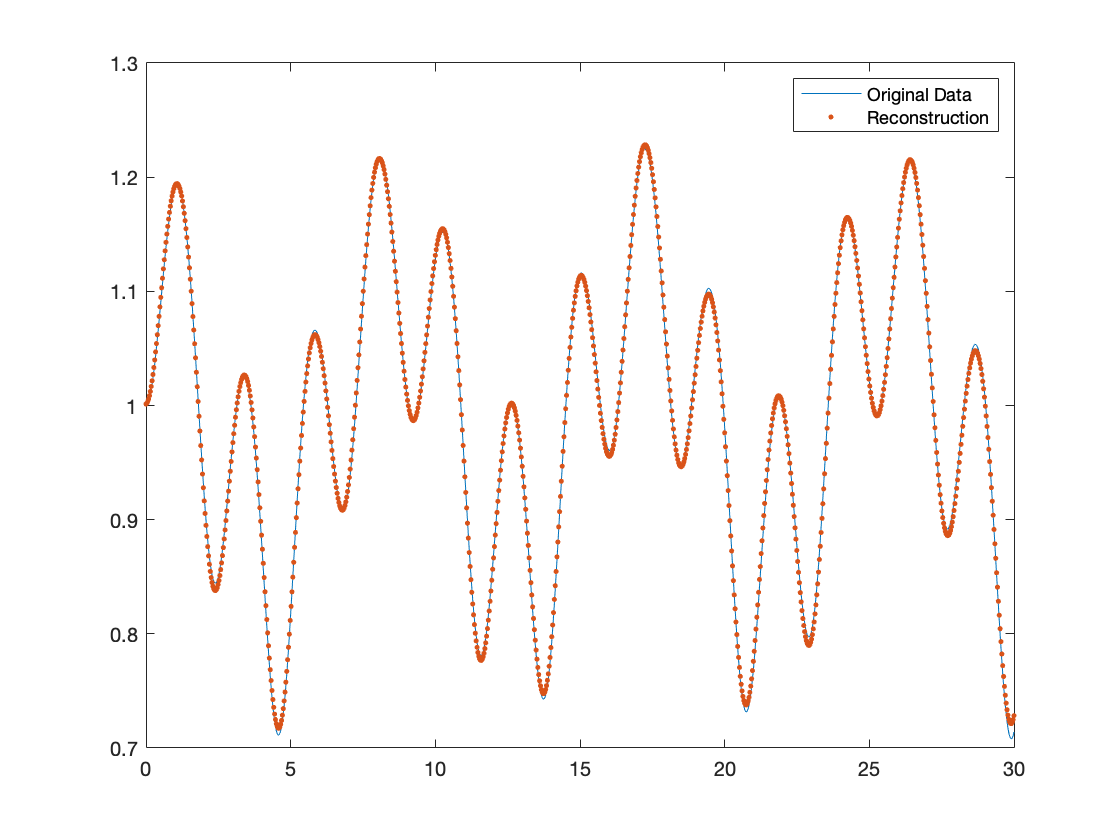

plot(t,V)
hold on
plot(t,real(Vreconst),'.')
legend("Original Data","Reconstruction")

% Import data from text file
% Script for importing data from the following text file:
%
%    filename: /Volumes/Rohith/College/SpatioTemporalKoopman/data/BTC-USD_daily-06_02-24_04.csv
%
% Auto-generated by MATLAB on 03-Jun-2021 10:10:32

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Close", "Var6", "Var7"];
opts.SelectedVariableNames = "Close";
opts.VariableTypes = ["string", "string", "string", "string", "double", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var6", "Var7"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var6", "Var7"], "EmptyFieldRule", "auto");

% Import the data
tbl = readtable("/Volumes/Rohith/College/SpatioTemporalKoopman/data/BTC-USD_daily-06_02-24_04.csv", opts);

% Convert to output type
Close = tbl.Close;

% Clear temporary variables
clear opts tbl

t = linspace(0,100,length(Close));
d = 46;
varepsilon1 = 10^-10;
varepsilon = 10^-4;
[Vreconst,~] =DMDd_SIADS(d,Close',t,varepsilon1,varepsilon)

Vreconst = 	1.0e+04 *

   3.9266 + 0.0000i   3.8704 - 0.0000i   4.5549 - 0.0000i   4.6551 - 0.0000i   4.4727 - 0.0000i   4.7383 + 0.0000i   4.6991 - 0.0000i   4.7382 - 0.0000i   4.8784 - 0.0000i   4.7714 - 0.0000i   4.9798 - 0.0000i   5.2818 + 0.0000i   5.1521 - 0.0000i   5.5362 + 0.0000i   5.5480 - 0.0000i   5.6482 - 0.0000i   5.2617 + 0.0000i   4.7264 + 0.0000i   4.9156 + 0.0000i   4.7010 - 0.0000i   4.6186 - 0.0000i   4.7082 - 0.0000i   4.6753 + 0.0000i   5.1205 - 0.0000i   5.0342 + 0.0000i   5.2481 - 0.0000i   5.0025 - 0.0000i   4.9202 + 0.0000i   4.7419 - 0.0000i   4.9050 + 0.0000i   4.9526 - 0.0000i   5.2784 - 0.0000i   5.6597 - 0.0000i   5.8688 + 0.0000i   5.8325 - 0.0000i   6.0027 - 0.0000i   6.0474 - 0.0000i   5.8511 - 0.0000i   6.0482 + 0.0000i   6.0778 + 0.0000i   5.8752 - 0.0000i   5.9279 - 0.0000i   5.9216 + 0.0000i   5.7555 + 0.0000i   5.4083 - 0.0000i   5.4909 + 0.0000i   5.3186 + 0.0000i   5.1892 + 0.0000i   5.4200 + 0.0000i   5.4683 + 0.0000i


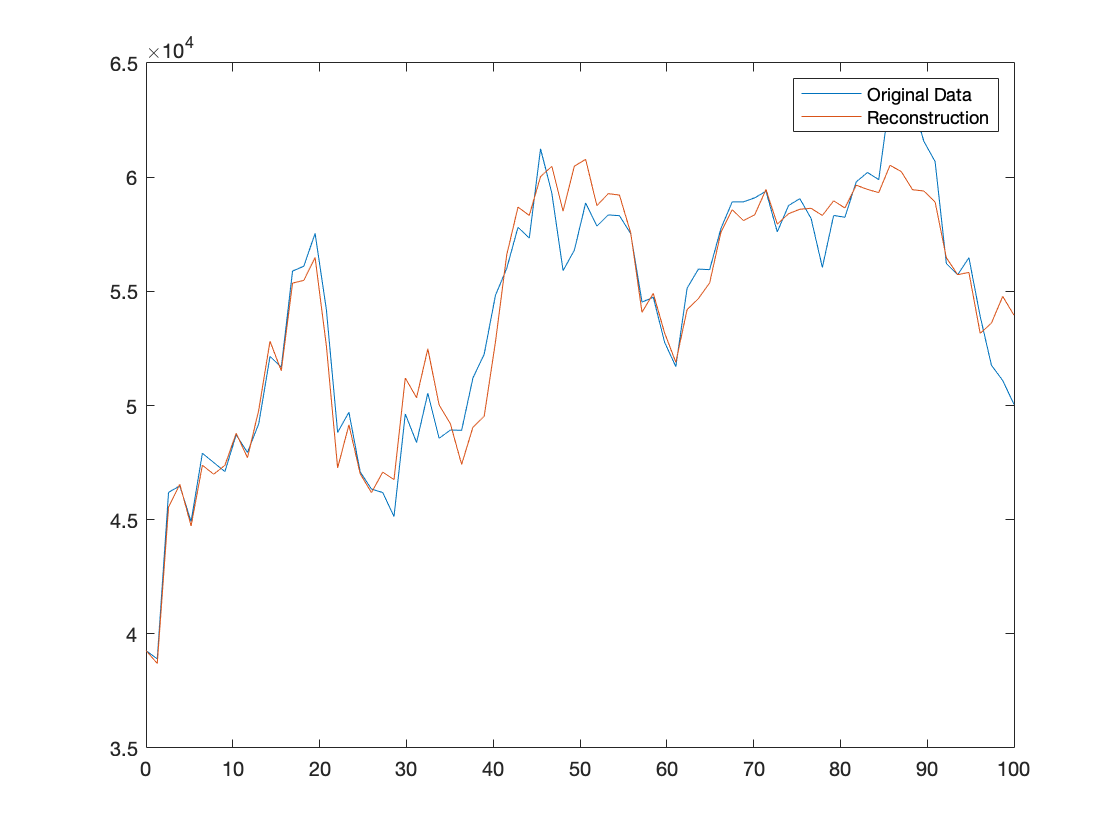

figure
plot(t,Close)
hold on
plot(t,real(Vreconst))
legend("Original Data","Reconstruction")

## Spatio Temporal Koopman Decomposition

For simplicity pupose we will consider one spatio-variable X and a temporal-variable T for and snapshot $V_1^k$ of dimension J x K.

Lets consider a toy model with discritised values $x_j$ = $x_1 +j\Delta x$  and $t_j$ = $t_1 +k\Delta t$, for j = 1,...,J and k = 1,....,K

STKD can be represented by 


$$\upsilon \left(x_j \;,t_k \right)\;=\sum_{m,n} a_{\textrm{mn}} \;u_{\textrm{mn}} \;e^{\left(v_m +ik_m \right)x_j +\left(\delta_n +i\omega_m \right)t_k }$$


$u_n$ are conveniently normalized spatial modes, $a_n$ > 0 are the mode amplitudes, and 𝛿𝑛 and 𝜔𝑛 ; $v_m \;\textrm{and}\;ik_m$ are the associated 

growth rates and frequencies, respectively. 

#### STEP : 1 -

As in HODMD, SVD is performed on the Snapshot $V_1^k$ with a tunable value $\epsilon_1$which determines the number of SVD modes M. 

$V_1^k$ = $P\sum Q^T$ $\equiv {\left(\hat{X_1^J } \right)}^T$$\hat{T_1^K }$,

$\hat{X_1^J }$ = $\sqrt{\sum }P^T$

$\hat{T_1^J }$ = $\sqrt{\sum }Q^T$

These matrices are the reduced spatial and temporal snapshots and their columns are $\hat{x_j }$and $\hat{t_k }$ are the reduced spatial and temporal snapshots.

#### STEP : 2 -

The HODMD algorithm is applied to thr spatial and temporal components

$\hat{x_j } \approx \sum_{m=1}^M {\hat{a_m } }^x \ldotp {\hat{q_m } }^x e^{\left(v_m +ik_m \right)x_j }$ , for j=1,...,J

$\hat{t_k } \approx \sum_{n=1}^N {\hat{a_n } }^t \ldotp {\hat{q_n } }^{t\;} e^{\left(\delta_n +i\omega_n \right)t_k }$ , for k=1,...,K

The numbers of retained modes, M and N, are the *spec- tral spatial and temporal complexities*, respectively, and are selected in terms of the spatial 

and temporal amplitudes, ${\hat{a_m } }^x$ and ${\hat{a_n } }^t$. M and N are the smallest values of the indexes 𝑚 and 𝑛 such that 


$$\frac{{\hat{a_{M+1} } }^x \;}{{\hat{a_1 } }^x }<\varepsilon_2$$



$$\frac{{\hat{a_{N+1} } }^x \;}{{\hat{a_1 } }^x }<\varepsilon_2$$


Illustration of the STKD in a toy model,		

u (𝑥, 𝑡) = (0.5 + sin 𝑥).[2.cos($k_1 \ldotp x-w_1 \ldotp t$) + (0.5).cos($k_2 \ldotp x-w_2 \ldotp t$)]

x = linspace(0,10,100);
t = linspace(0,100,100);
U = zeros(length(x));

varepsilon1 = 10^-8;
varepsilon2 = 10^-7;

for i=1:length(x)
    for j=1:length(t)
        X = x(i); T = t(j);
        U(i,j) = (0.5 + sin(X)) * (2*cos(2*X - (2*pi/45)*T) + 0.5*cos(10*X - sqrt(10)*T));
    end
end
figure
[Vreconst,Modes,Amplitudes,Amplitudesx,GrowthRatex,Frequencyx,Amplitudest,GrowthRatet,Frequencyt]=...
CalculateDMDdSdT(10,1,x,t,U,varepsilon1,varepsilon2);

Spatial Dimension: singular values
     4

Spatial dimension reduction
    12

size of a


ans =     12     1


size of Q


ans =      4    12


Spectral complexity
    12



ans = 'Spectral complexity'

kk3 = 4

    48

    12

Number of spatial modes
    12

Number of temporal modes
     4



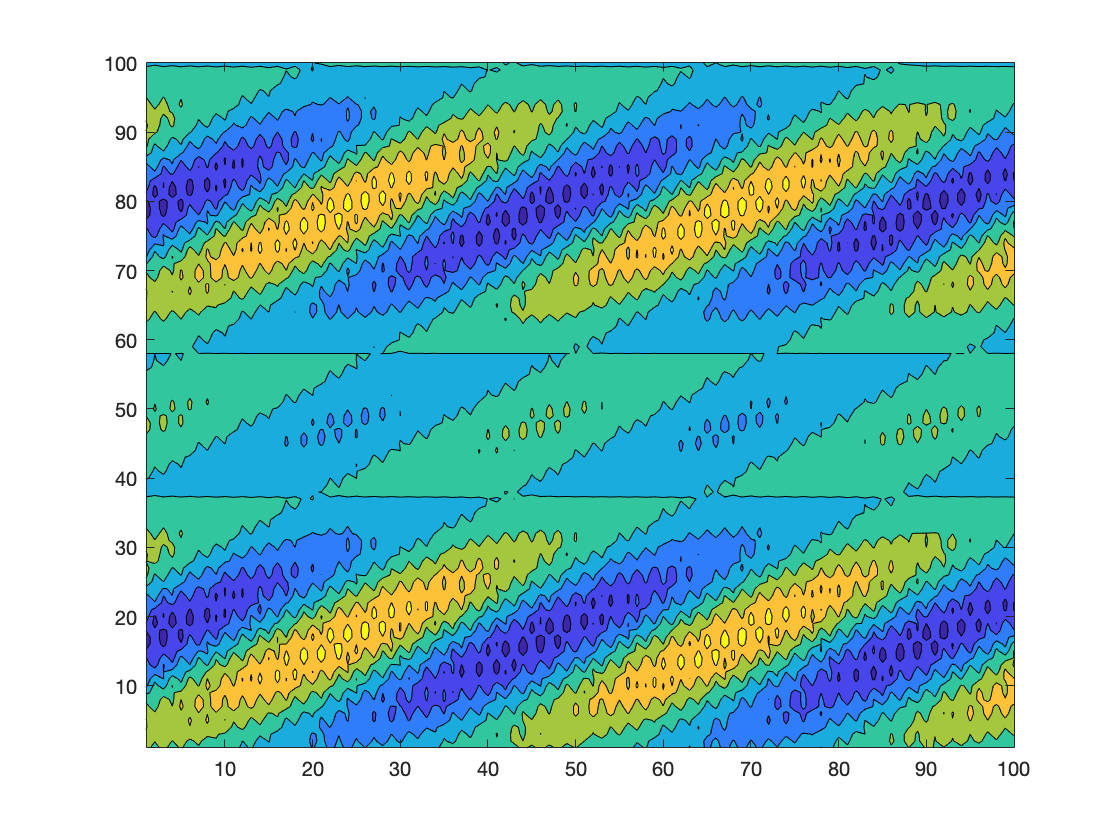

contourf(U)

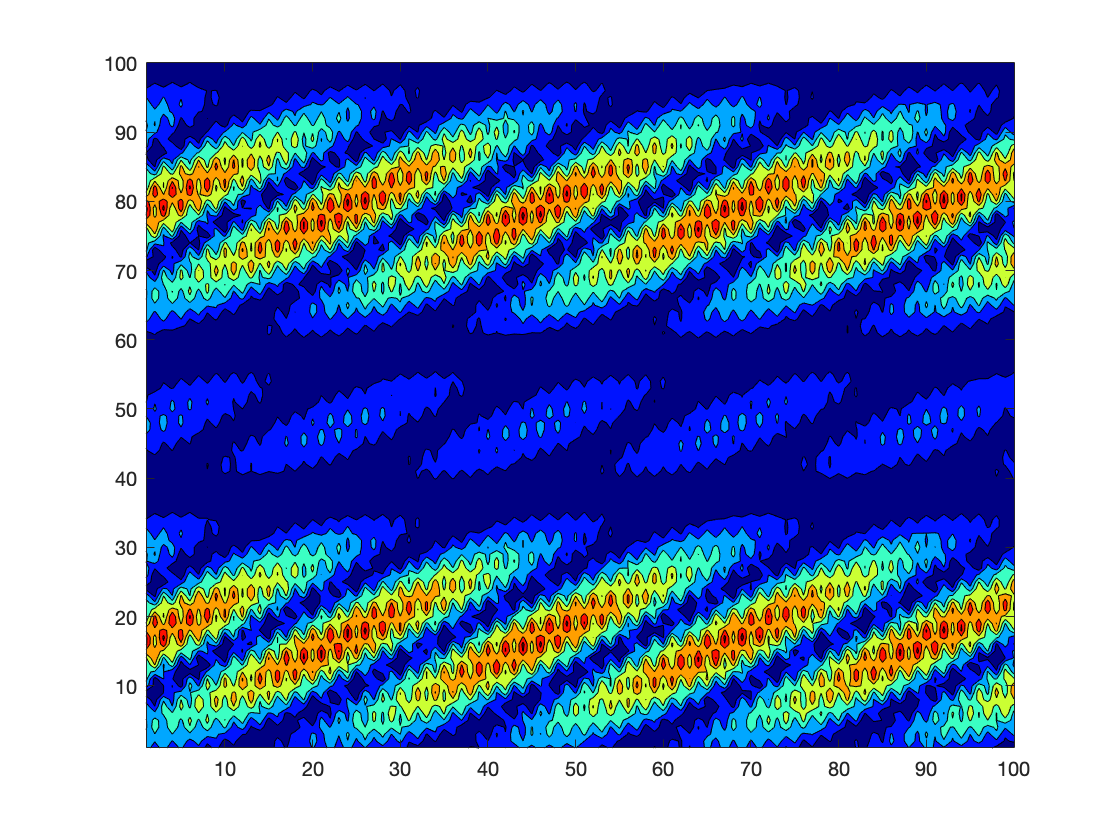

figure
contourf(abs(Vreconst))
shading('interp')
colormap(jet)

# Stock Prediction via STKD

The information shared on social media generates sentiments and reactions in investors that influence their decisions to buy or sell financial assets, especially on the stock market [1]. News shared on social media, whether true or not, cause changes in the trends of international stock market indices [2]. Some studies confirm the relationship between sentiments generated by social media in investors and market trends, and the current study continues this path in exploring pandemic periods with a lexicon-based approach to detect polarity in financial news on Twitter.

Our hypothesis is that sentiments expressed via Tweets and News can cause a potential change in stock and could be a crucial factor for predicting very volatile prices such as **Cryptocurrency**.In the recent times, we saw hoe Elon Musks Tweets single handed brought down the price of Bitcoin and sky-rocketted Dogecoin's price.

In the experiment performed we will be collecting News and Tweets and analysiong the sentiments of the same which will act as the spatial component of our analysis and temporal being time.

### Bitcoin prediction with Tweets

For this experiment tweets between 6th February to 24th April 2021 were collected along with the closing price of Bitcoin in the same Date range. The collected tweet swill have numerous tweets for any given day hence an mean of all the sentiments for the day was taken.

The sentiment analysis was done in python using *'nlptown/bert-base-multilingual-uncased-sentiment' *

*The above code corresponds to the python script for extracting sentiments.*

SInce the data isnt very huge, a single snapshot will will very sparse.

clc
clear all

load sent_snp.mat
V = sent;
s = size(V);
Time = linspace(0,1,s(2));
Exis = linspace(0,1,s(1));


% APPLY STKD TO V
[J,K]=size(V);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% STKD  PARAMETERS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% SET PARAMETERS STKD
% Tolerances
% SVD
varepsilon1=1e-8;
% DMD
varepsilon2=1e-7;
% Set index d: dSpace for spatial analysis and dTime for temporal analysis
dSpace=2;
dTime=1;

[Vreconst,Modes,Amplitudes,Amplitudesx,GrowthRatex,Frequencyx,Amplitudest,GrowthRatet,Frequencyt]=...
CalculateDMDdSdT(dSpace,dTime,Time,Exis,V,varepsilon1,varepsilon2);

Spatial Dimension: singular values
    18

Spatial dimension reduction
    20



size of a


ans =     20     1


size of Q


ans =     18    20


Spectral complexity
    20



ans = 'Spectral complexity'

kk3 = 18

   360

   360

Number of spatial modes
    20

Number of temporal modes
    18




% CALCULATE RRMS ERROR
dif=Vreconst-V;
errorRMS=norm(dif(:))/norm(V(:));
disp('Reconstruction error: RRMSE')

Reconstruction error: RRMSE


disp(errorRMS)

    0.9540



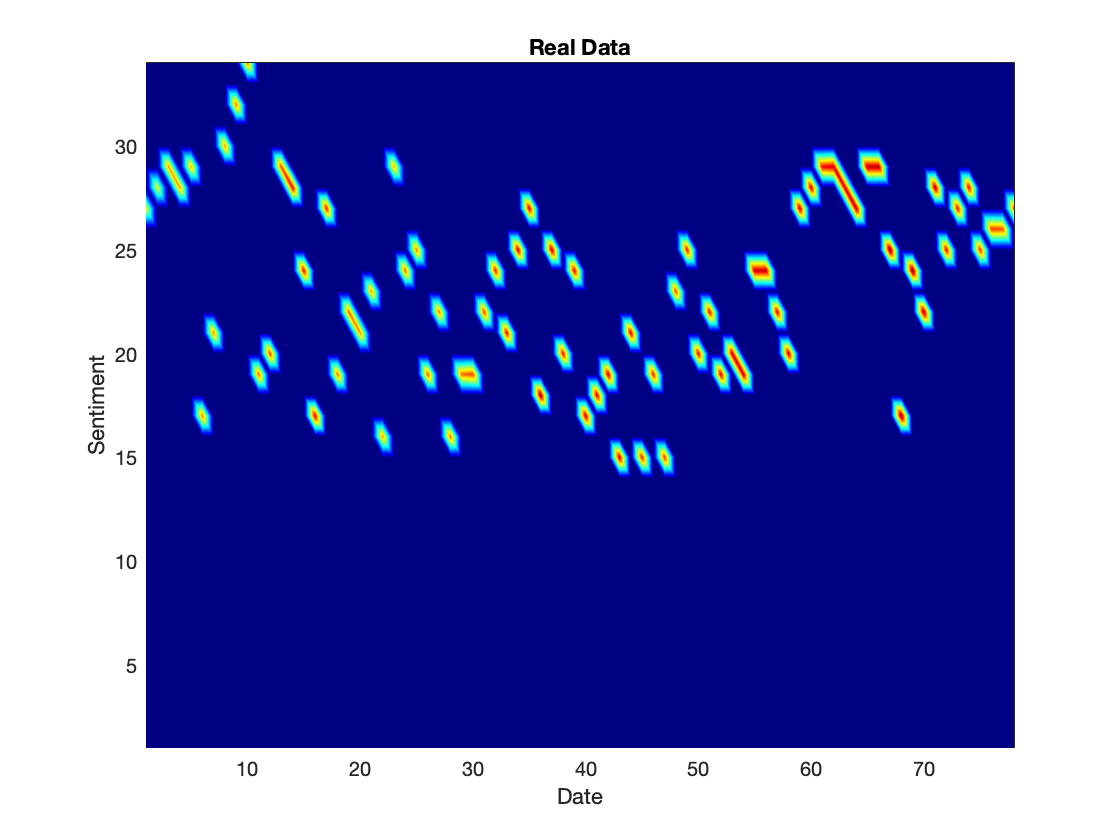

% PLOT RECONSTRUCTION
figure
pcolor(V)
shading('interp')
colormap(jet)
xlabel('Date')
ylabel('Sentiment')
title("Real Data")

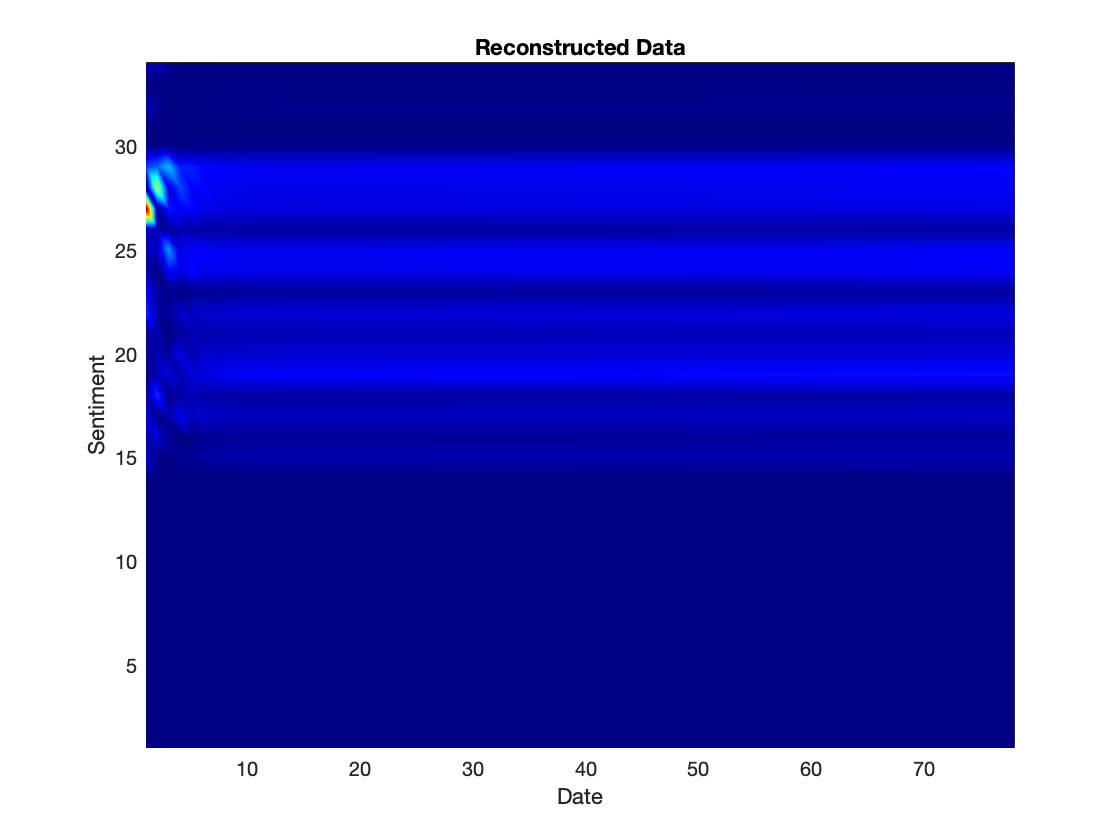


h9=figure;
axes9 = axes('Parent',h9,'FontSize',14,'FontName','Agency FB');
box(axes9,'on');
pcolor(abs(Vreconst))
shading('interp')
colormap(jet)
xlabel('Date')
ylabel('Sentiment')
title("Reconstructed Data")

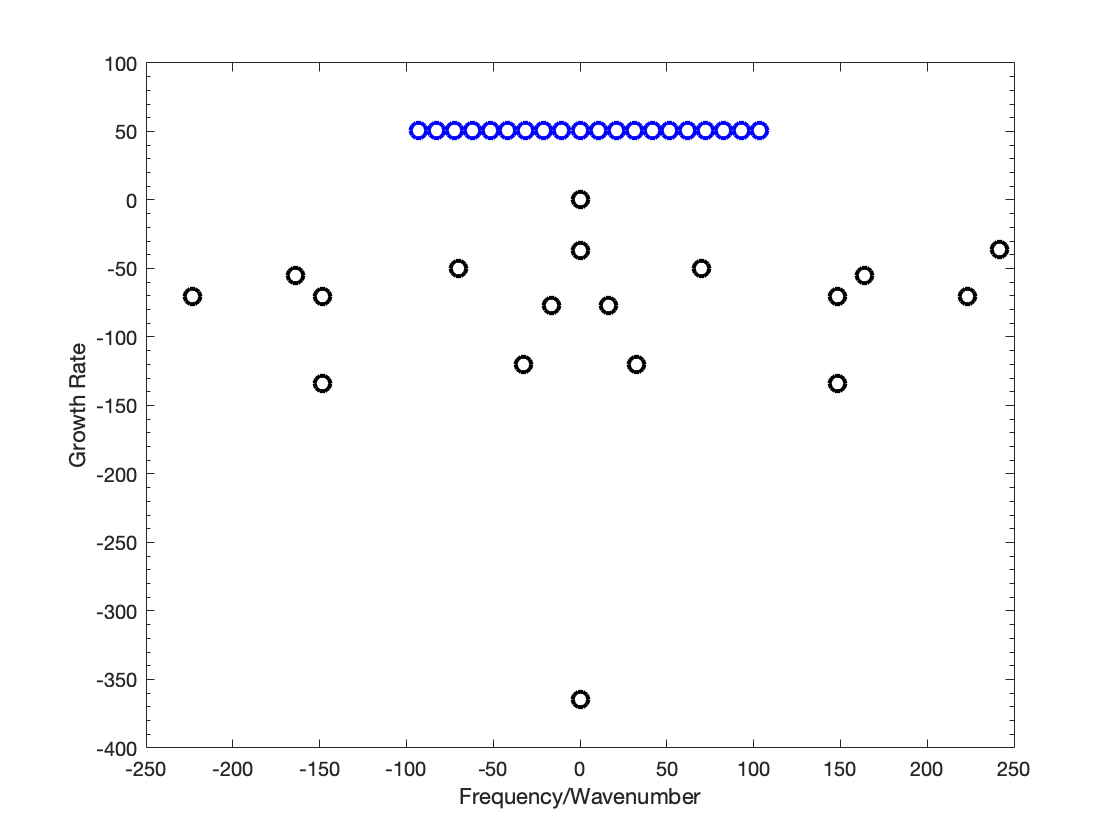

% Plot: frequency/wavenumber vs. amplitude, vs. growth rate
figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
box(axes1,'on');
semilogy(Frequencyt,GrowthRatet,'o','linewidth',2,'color','k','MarkerSize',8);
semilogy(Frequencyx,GrowthRatex,'o','linewidth',2,'color','b','MarkerSize',8);
set(axes1,'YMinorTick','on');
xlabel('Frequency/Wavenumber')
ylabel('Growth Rate')

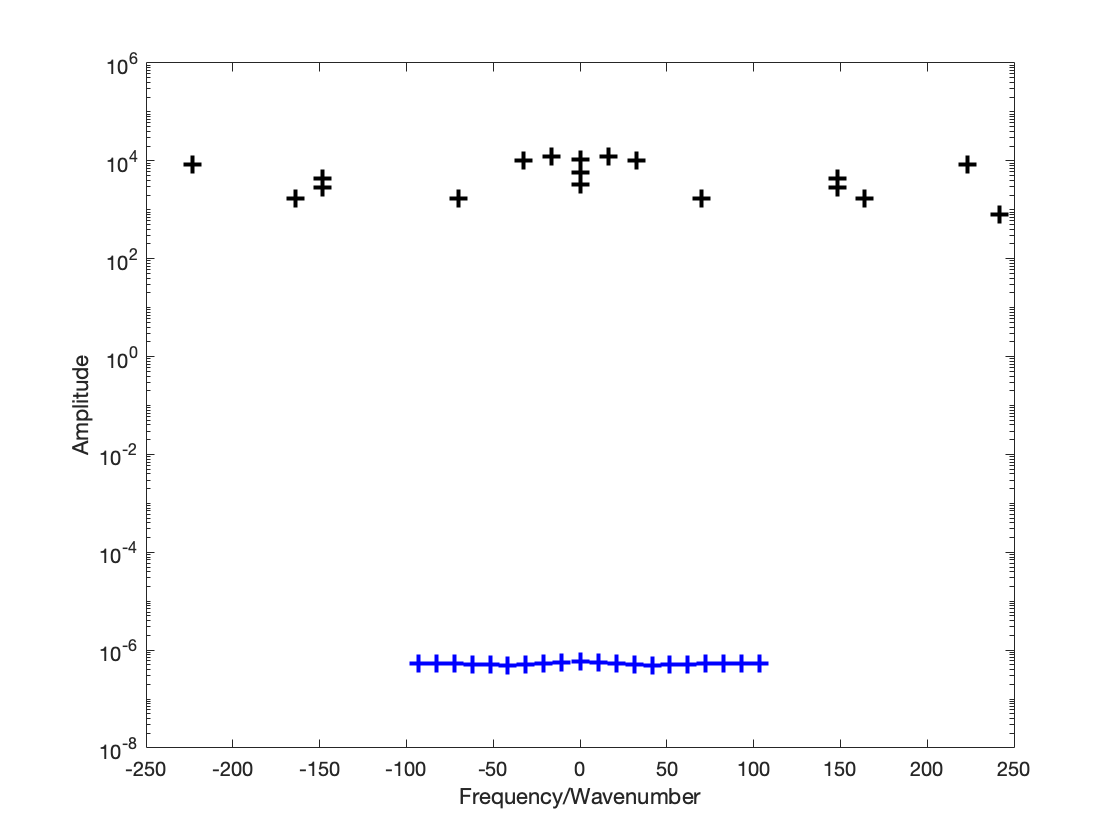

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
box(axes1,'on');
semilogy(Frequencyt,Amplitudest,'+','linewidth',2,'color','k','MarkerSize',8);
semilogy(Frequencyx,Amplitudesx,'+','linewidth',2,'color','b','MarkerSize',8);
set(axes1,'YMinorTick','on','YScale','log');
xlabel('Frequency/Wavenumber')
ylabel('Amplitude')

figure

### Dogecoin prediction with News Sentiments

Similar to the Bitcoin approach, news was collected for the past 2 years -  1st January 2019 to 3rd June 2021. 

`The full notebook can be found here : `[https://colab.research.google.com/drive/1YeivODqLAZtZiSBbuot7vV_T8ZkFzwEF?usp=sharing](https://colab.research.google.com/drive/1YeivODqLAZtZiSBbuot7vV_T8ZkFzwEF?usp=sharing)

clear all
clc
%Import data from text file
% Script for importing data from the following text file:
%
%    filename: /Volumes/Rohith/College/SpatioTemporalKoopman/scripts/Matrix.csv
%
% Auto-generated by MATLAB on 02-Jun-2021 23:38:47

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 304);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["e00", "e00_1", "e00_2", "e00_3", "e00_4", "e00_5", "e00_6", "e00_7", "e00_8", "e00_9", "e00_10", "e00_11", "e00_12", "e00_13", "e00_14", "e00_15", "e00_16", "e00_17", "e00_18", "e00_19", "e00_20", "e00_21", "e00_22", "e00_23", "e00_24", "e00_25", "e00_26", "e00_27", "e00_28", "e00_29", "e00_30", "e00_31", "e00_32", "e00_33", "e00_34", "e00_35", "e00_36", "e00_37", "e00_38", "e00_39", "e00_40", "e00_41", "e00_42", "e00_43", "e00_44", "e00_45", "e00_46", "e00_47", "e00_48", "e00_49", "e00_50", "e00_51", "e00_52", "e00_53", "e00_54", "e00_55", "e00_56", "e00_57", "e00_58", "e00_59", "e00_60", "e00_61", "e00_62", "e00_63", "e00_64", "e00_65", "e00_66", "e00_67", "e00_68", "e00_69", "e00_70", "e00_71", "e00_72", "e00_73", "e00_74", "e00_75", "e00_76", "e00_77", "e00_78", "e00_79", "e00_80", "e00_81", "e00_82", "e00_83", "e00_84", "e00_85", "e00_86", "e00_87", "e00_88", "e00_89", "e00_90", "e00_91", "e00_92", "e00_93", "e00_94", "e00_95", "e00_96", "e00_97", "e00_98", "e00_99", "e00_100", "e00_101", "e00_102", "e00_103", "e00_104", "e00_105", "e00_106", "e00_107", "e00_108", "e00_109", "e00_110", "e00_111", "e00_112", "e00_113", "e00_114", "e00_115", "e00_116", "e00_117", "e00_118", "e00_119", "e00_120", "e00_121", "e00_122", "e00_123", "e00_124", "e00_125", "e00_126", "e00_127", "e00_128", "e00_129", "e00_130", "e00_131", "e00_132", "e00_133", "e00_134", "e00_135", "e00_136", "e00_137", "e00_138", "e00_139", "e00_140", "e00_141", "e00_142", "e00_143", "e00_144", "e00_145", "e00_146", "e00_147", "e00_148", "e00_149", "e00_150", "e00_151", "e00_152", "e00_153", "e00_154", "e00_155", "e00_156", "e00_157", "e00_158", "e00_159", "e00_160", "e00_161", "e00_162", "e00_163", "e00_164", "e00_165", "e00_166", "e00_167", "e00_168", "e00_169", "e00_170", "e00_171", "e00_172", "e00_173", "e00_174", "e00_175", "e00_176", "e00_177", "e00_178", "e00_179", "e00_180", "e00_181", "e00_182", "e00_183", "e00_184", "e00_185", "e00_186", "e00_187", "e00_188", "e00_189", "e00_190", "e00_191", "e00_192", "e00_193", "e00_194", "e00_195", "e00_196", "e00_197", "e00_198", "e00_199", "e00_200", "e00_201", "e00_202", "e00_203", "e00_204", "e00_205", "e00_206", "e00_207", "e00_208", "e00_209", "e00_210", "e00_211", "e00_212", "e00_213", "e00_214", "e00_215", "e00_216", "e00_217", "e00_218", "e00_219", "e00_220", "e00_221", "e00_222", "e00_223", "e00_224", "e00_225", "e00_226", "e00_227", "e00_228", "e00_229", "e00_230", "e00_231", "e00_232", "e00_233", "e00_234", "e00_235", "e00_236", "e00_237", "e00_238", "e00_239", "e00_240", "e00_241", "e00_242", "e00_243", "e00_244", "e00_245", "e00_246", "e00_247", "e00_248", "e00_249", "e00_250", "e00_251", "e00_252", "e00_253", "e00_254", "e00_255", "e00_256", "e00_257", "e00_258", "e00_259", "e00_260", "e00_261", "e00_262", "e00_263", "e00_264", "e00_265", "e00_266", "e00_267", "e00_268", "e00_269", "e00_270", "e00_271", "e00_272", "e00_273", "e00_274", "e00_275", "e00_276", "e00_277", "e00_278", "e00_279", "e00_280", "e00_281", "e00_282", "e00_283", "e00_284", "e00_285", "e00_286", "e00_287", "e00_288", "e00_289", "e00_290", "e00_291", "e00_292", "e00_293", "e00_294", "e00_295", "e00_296", "e00_297", "e00_298", "e00_299", "e00_300", "e00_301", "e00_302", "e00_303"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Matrix = readtable("/Volumes/Rohith/College/SpatioTemporalKoopman/scripts/Matrix.csv", opts);

% Convert to output type
Matrix = table2array(Matrix);

% Clear temporary variables
clear opts

V = 100*Matrix;
s = size(V);
Time = linspace(0,1,s(2));
Exis = linspace(0,1,s(1));



% APPLY STKD TO V
[J,K]=size(V);
for i=1:J
    for j = 1:K
        if(isnan(V(i,j)))
           V(i,j) = 0;
        end
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% STKD  PARAMETERS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% SET PARAMETERS STKD
% Tolerances
% SVD
varepsilon1=1e-20;
% DMD
varepsilon2=1e-18;
% Set index d: dSpace for spatial analysis and dTime for temporal analysis
dSpace=25;
dTime=25;

[Vreconst,Modes,Amplitudes,Amplitudesx,GrowthRatex,Frequencyx,Amplitudest,GrowthRatet,Frequencyt]=...
CalculateDMDdSdT(dSpace,dTime,Time,Exis,V,varepsilon1,varepsilon2);

Spatial Dimension: singular values
    50

Spatial dimension reduction
    26

size of a


ans =     26     1


size of Q


ans =     50    26


Spectral complexity
    26

Spatial dimension reduction
   280

size of a


ans =    280     1


size of Q


ans =     50   280


Spectral complexity
   280



        7280

        7280

Number of spatial modes
    26

Number of temporal modes
   280




% CALCULATE RRMS ERROR
dif=Vreconst-V;
errorRMS=norm(dif(:))/norm(V(:));
disp('Reconstruction error: RRMSE')

Reconstruction error: RRMSE


disp(errorRMS)

    0.9998



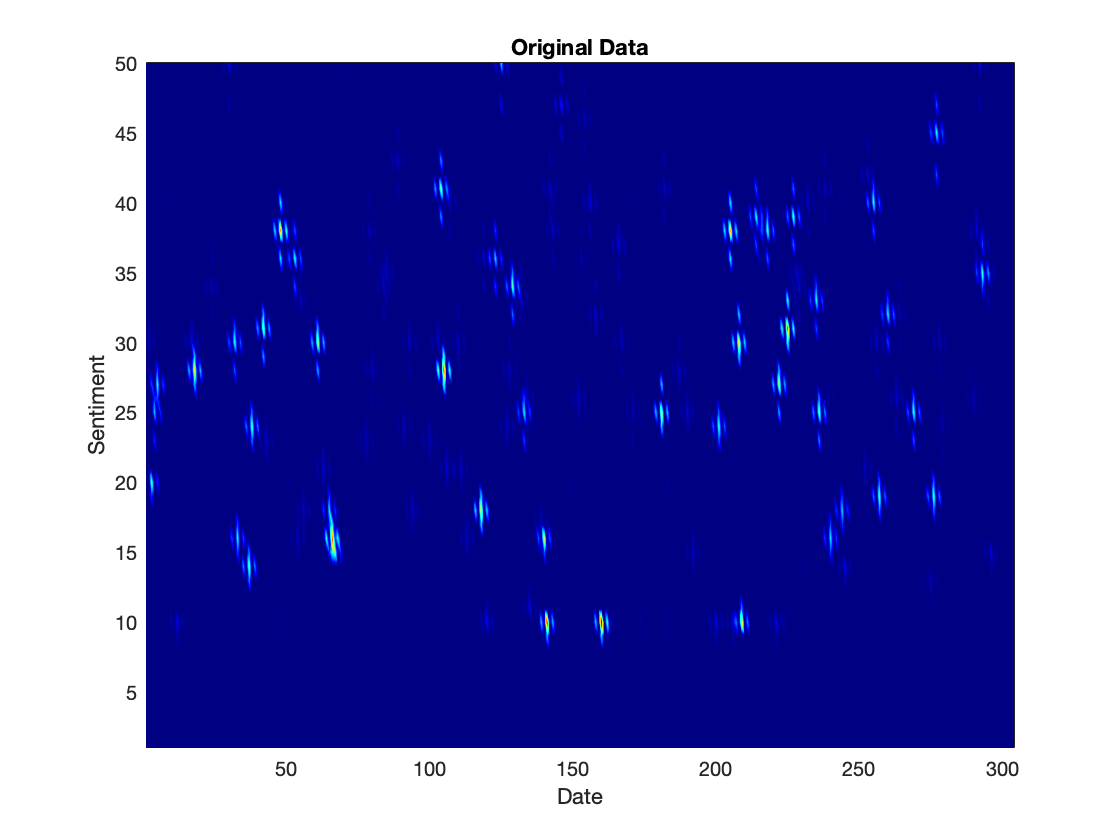

% PLOT RECONSTRUCTION
figure
pcolor(V)
shading('interp')
colormap(jet)
xlabel('Date')
ylabel('Sentiment')
title("Original Data")

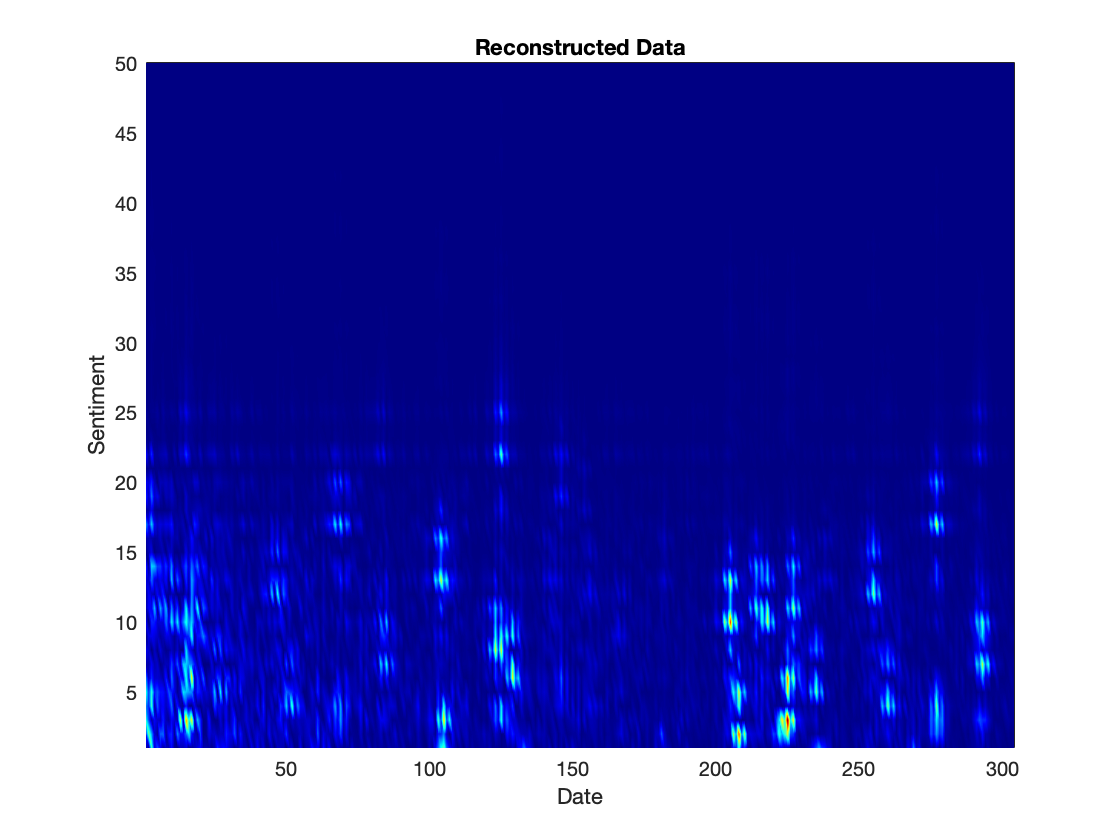


h9=figure;
axes9 = axes('Parent',h9,'FontSize',14,'FontName','Agency FB');
box(axes9,'on');
pcolor(abs(Vreconst))
shading('interp')
colormap(jet)
xlabel('Date')
ylabel('Sentiment')
title("Reconstructed Data")

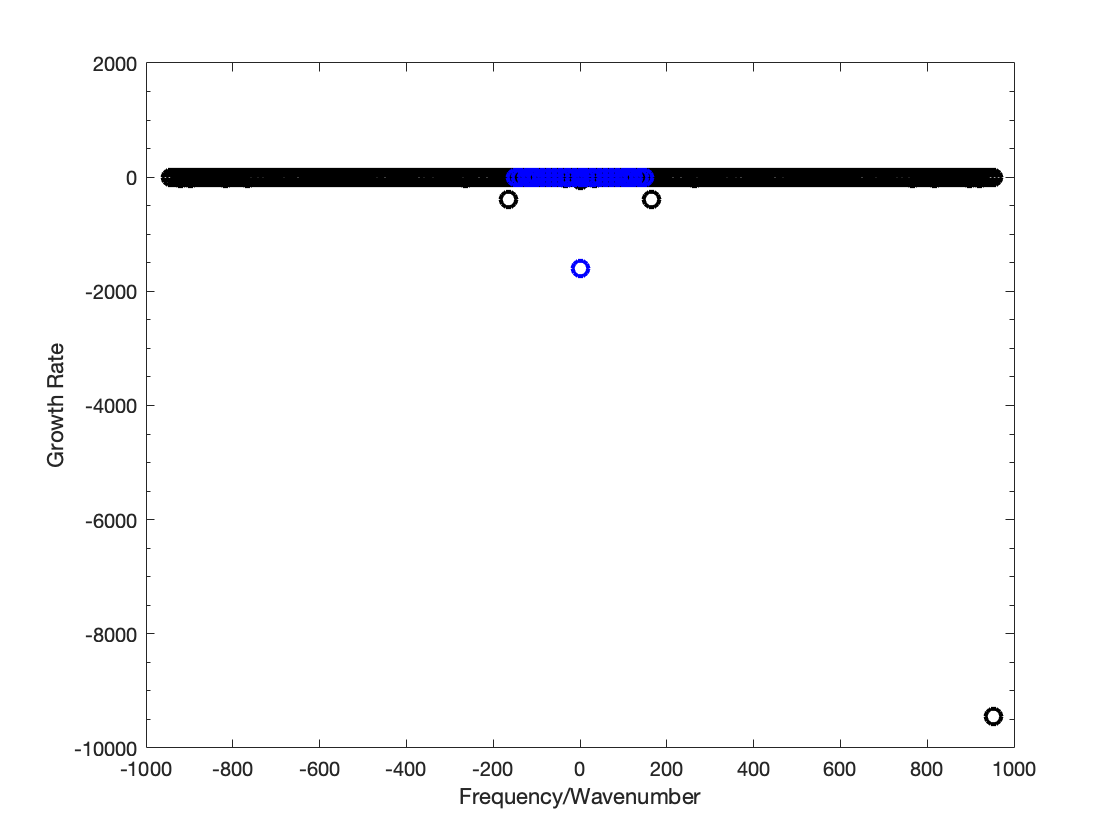



% Plot: frequency/wavenumber vs. amplitude, vs. growth rate
figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
box(axes1,'on');
semilogy(Frequencyt,GrowthRatet,'o','linewidth',2,'color','k','MarkerSize',8);
semilogy(Frequencyx,GrowthRatex,'o','linewidth',2,'color','b','MarkerSize',8);
set(axes1,'YMinorTick','on');
xlabel('Frequency/Wavenumber')
ylabel('Growth Rate')

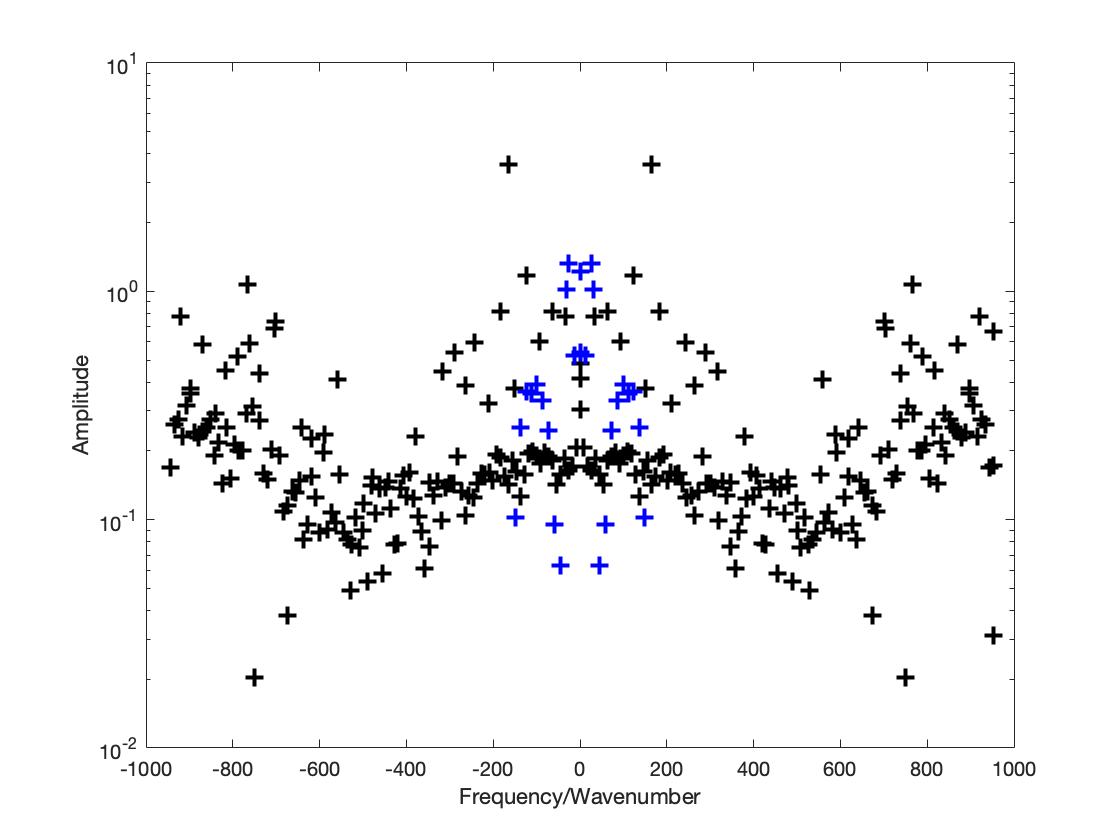

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
box(axes1,'on');
semilogy(Frequencyt,Amplitudest,'+','linewidth',2,'color','k','MarkerSize',8);
semilogy(Frequencyx,Amplitudesx,'+','linewidth',2,'color','b','MarkerSize',8);
set(axes1,'YMinorTick','on','YScale','log');
xlabel('Frequency/Wavenumber')
ylabel('Amplitude')

### Conclusion

From the above experiments we can see that the snapshots (Data Matrix) is very sparse and STKD is not very sucessful in reconstrcting the snapshot. A few reasons could be/scope of improvement:

- Incorrect Choice of Space Variable

- Use of improved Sentiment Analyser

- Hypertuning parameters of STKD

- Restriction in Data Collection

- More weightage to Tweets from celebrities (eg:Elon Musk's tweet would be more important than any unknown individual)

Despite the result, this experiment was conducted to analyse if sentiments from twitter and News could potentially aid in predicting Volatile Markets. These experiments would be a base for further improvement and analysis.

#### Reference

[1] Kearney C, Liu S. Textual sentiment in finance: a survey of methods and models. Int Rev Financ Anal. 2014;33:171–85.

[2] Jiao P, Veiga A, Walther A. Social media, news media and the stock market. J Econ Behav Organ. 2020;176:63–90.

#### Appendix

function  [Vreconst,deltas,omegas,amplitude,modes] =DMDd_SIADS(d,V,Time,varepsilon1,varepsilon)


%%%%%%%%%%%%%%%%%%%%%%%%%  DMD-d %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% This function solves the HODMD algorithm presented in               %%%
%%% Le Clainche & Vega, SIAM J. on Appl. Dyn. Sys. 16(2):882-925, 2017  %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% %% INPUT: %%
%%% d: parameter of DMD-d (higher order Koopman assumption)
%%% V: snapshot matrix
%%% Time: vector time
%%% varepsilon1: first tolerance (SVD)
%%% varepsilon: second tolerance (DMD-d modes)
%%% %% OUTPUT: %%
%%% Vreconst: reconstruction of the snapshot matrix V
%%% deltas: growht rate of DMD modes
%%% omegas: frequency of DMD modes(angular frequency)
%%% amplitude: amplitude of DMD modes
%%% modes: DMD modes
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


[J,K]=size(V);

% STEP 1: SVD of the original data

[U,Sigma,T]=svd(V,'econ');
sigmas=diag(Sigma);
n=length(sigmas);

NormS=norm(sigmas,2);
kk=0;
for k=1:n
    if norm(sigmas(k:n),2)/NormS>varepsilon1
        kk=kk+1;
    end
end

U=U(:,1:kk);

% Create reduced snapshots matrix
hatT=Sigma(1:kk,1:kk)*T(:,1:kk)';
[N,~]=size(hatT);

% Create the modified snapshot matrix
tildeT=zeros(d*N,K-d+1);
for ppp=1:d
    tildeT((ppp-1)*N+1:ppp*N,:)=hatT(:,ppp:ppp+K-d);
end

% Dimension reduction
[U1,Sigma1,T1]=svd(tildeT,'econ');
sigmas1=diag(Sigma1);

Deltat=Time(2)-Time(1);
n=length(sigmas1);

NormS=norm(sigmas1,2);
kk1=0;
for k=1:n
    RRMSEE(k)=norm(sigmas1(k:n),2)/NormS;
    if RRMSEE(k)>varepsilon1
        kk1=kk1+1;
    end
end


U1=U1(:,1:kk1);
hatT1=Sigma1(1:kk1,1:kk1)*T1(:,1:kk1)';

% Reduced modified snapshot matrix
[~,K1]=size(hatT1);
[tildeU1,tildeSigma,tildeU2]=svd(hatT1(:,1:K1-1),'econ');

% Reduced modified Koopman matrix
tildeR=hatT1(:,2:K1)*tildeU2*inv(tildeSigma)*tildeU1';
[tildeQ,tildeMM]=eig(tildeR);
eigenvalues=diag(tildeMM);

M=length(eigenvalues);
qq=log(eigenvalues);
deltas=real(qq)/Deltat;
omegas=imag(qq)/Deltat;

Q=U1*tildeQ;
Q=Q((d-1)*N+1:d*N,:);
[NN,MMM]=size(Q);

for m=1:MMM
    NormQ=Q(:,m);
    Q(:,m)= Q(:,m)/norm(NormQ(:),2);
end

% Calculate amplitudes
Mm=zeros(NN*K,M);
Bb=zeros(NN*K,1);
aa=eye(MMM);
for k=1:K
    Mm(1+(k-1)*NN:k*NN,:)=Q*aa;
    aa=aa*tildeMM;
    Bb(1+(k-1)*NN:k*NN,1)=hatT(:,k);
end

[Ur,Sigmar,Vr]=svd(Mm,'econ');
a=Vr*(Sigmar\(Ur'*Bb));

u=zeros(NN,M);
for m=1:M
    u(:,m)=a(m)*Q(:,m);
end
amplitude=zeros(M,1);

for m=1:M
    aca=U*u(:,m);
    amplitude(m)=norm(aca(:),2)/sqrt(J);
end

UU=[u;deltas';omegas';amplitude']';
UU1=sortrows(UU,-(NN+3));

UU=UU1';
u=UU(1:NN,:);
deltas=UU(NN+1,:);
omegas=UU(NN+2,:);
amplitude=UU(NN+3,:);
kk3=0;

for m=1:M
    if amplitude(m)/amplitude(1)>varepsilon
        kk3=kk3+1;
    else
    end
end

u=u(:,1:kk3);
deltas=deltas(1:kk3);
omegas=omegas(1:kk3);
amplitude=amplitude(1:kk3);

% Reconstruction of the original snapshot matrix
hatTreconst=zeros(N,K);
for k=1:K
    hatTreconst(:,k)= ContReconst_SIADS(Time(k),Time(1),u,deltas,omegas);
end

Vreconst=U*hatTreconst;

% Calculation of DMD modes
modes=zeros(J,kk3);
amplitude0=zeros(kk3,1);
for m=1:kk3
    NormMode=norm(U*u(:,m),2)/sqrt(J);
    amplitude0(m)=NormMode;
    modes(:,m)=U*u(:,m)/NormMode;
end
end